Creating the Learning Factory Environment

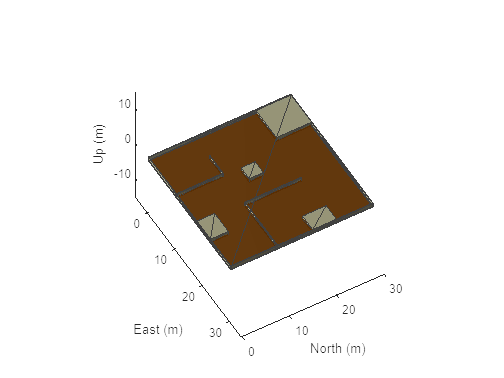

envc = EnvironmentConstants();
[obstacles, scenario, gridSize] = envc.createRobotScenerioEnvironment3();
show3D(scenario);
lightangle(-45,30);
view(60,50);

Reinforcement Learning stuff

points = [];
counter = 0

counter = 0

rng(69)
while counter < 12
    counter = counter + 1;

    isvalid = false;
    while ~isvalid        
        rows = randperm(gridSize(1),1);
        cols = randperm(gridSize(2),1);
        position = [rows' cols'];
        if ~isempty(points)
            if ~any(ismember(position, obstacles, 'rows')) && ~any(ismember(position, points, 'rows')) 
                isvalid = true;
                points = [points; position];
            end
        elseif ~any(ismember(position, obstacles, 'rows')) 
            isvalid = true;
            points = position;
        end
    end
end
points

points =      9    25
    11    24
    17     8
     4     2
    21    21
    22    24
     3    10
    15     6
    10    14
    16     9


fname = sprintf('experiment_points/experiment_3_points', 'points');
save(fname)
 